# Individual Design Analysis

## Cleaning

clear;
clc;

## Variables

% Provided flat plate CL and CD values with respect to AOA
plateCl = [-.75 -.76 -.77 -.78 -0.8 -0.78 -.76 -.74 -.7 -.6 -.5 -.38 -.3 -.2 -.1 0 .1 .2 .3 .4 .49 .6 .7 .75 .76 .77 .76 .75 .75 .74 .74 .73 .72 .71 .71 .7];
plateCd = [.21 .2 .19 .18 .17 .15 .13 .11 .09 .07 .05 .04 .02 .01 .005 0  .005 .01 .015 .02 .05 .065 0.09 .11 .13 .15 .17 .19 .199 .21 .22 .23 .25 .27 .285 .29];
plateAOA = [-15:1:20];
ReCr = 140000;

% Design properties
Swet = 0.3025*2 % Wetted area [m^2]

Swet = 0.6050

Sref = 0.2085 % Wing planform area [m^2]

Sref = 0.2085

b = 0.9 % Wing span [m]

b = 0.9000

AR = 3.885 % Aspect ratio

AR = 3.8850

lambda = .2857 % Taper ratio

lambda = 0.2857

W = 0.295 * 9.81 * Sref % Approximate weight [N]

W = 0.6034

mass = W / 9.81 % Weight [kg]

mass = 0.0615

e = 0.9 % Estimated span efficiency factor

e = 0.9000

V = 7 % Velocity [m/s]

V = 7

## Analysis

% Estimated Lift Curve
fit2D = polyfit(plateAOA, plateCl, 1); % Best fit line for Cl vs AOA
a0 = fit2D(1) % Save value of slope

a0 = 0.0574

fit2D = polyfit(plateCl, plateAOA, 1); % Best fit line for flipping axes
angle0lift = polyval(fit2D, 0) % Angle of attack at 0 lift

angle0lift = 0.9937

a = a0 / (1 + (57.3 * a0)/(pi * e * AR)) % 3D lift slope

a = 0.0442

calcCL = a .* (plateAOA - angle0lift) % 3D coefficient of lift

calcCL =    -0.7068   -0.6626   -0.6184   -0.5743   -0.5301   -0.4859   -0.4417   -0.3975   -0.3533   -0.3091   -0.2649   -0.2207   -0.1765   -0.1323   -0.0881   -0.0439    0.0003    0.0445    0.0887    0.1329    0.1771    0.2213    0.2655    0.3096    0.3538    0.3980    0.4422    0.4864    0.5306    0.5748    0.6190    0.6632    0.7074    0.7516    0.7958    0.8400


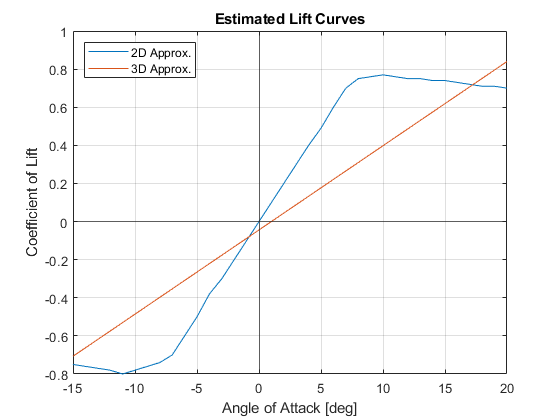


plot(plateAOA, plateCl)
hold on;
plot(plateAOA, calcCL)
yline(0);
xline(0);
hold off;
grid on;
title('Estimated Lift Curves') % Might want to change this title for submission
xlabel('Angle of Attack [deg]')
ylabel('Coefficient of Lift')
legend('2D Approx.', '3D Approx.', 'Location', 'Northwest')


% Estimated Whole Aircraft Drag Polar
% Air properties assuming altitude of 1500 m
mu = 1.74 * 10^-5 % Air viscosity [kg/m*s]

mu = 1.7400e-05

rhoAlt = 1.0581 % Air density [kg/m^3]

rhoAlt = 1.0581

ReL = 1000000

ReL = 1000000


xCr = (ReCr * mu) / (rhoAlt * V)

xCr = 0.3289

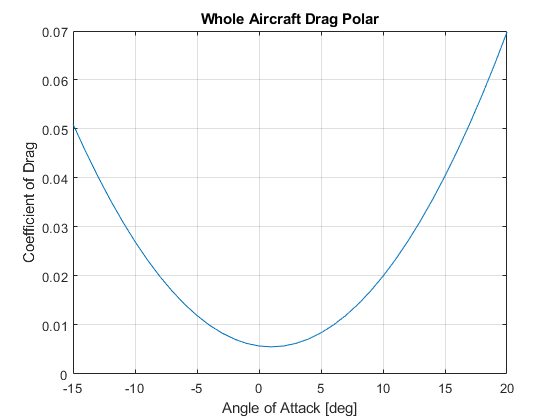

CfTurbTotal = 0.074/(ReL^0.2); % Total Wing Turbulent Cf
CfTurbLeft = 0.0592/(ReCr^0.2); % Turbulent Cf to be subtracted from total
CfLamLeft = 0.664/sqrt(ReCr); % Laminar Cf
CfTotal = 2*(CfTurbTotal - CfTurbLeft + CfLamLeft); % Total Cf for both wings

CDMin = CfTotal * (Swet / Sref);
CDwing = plateCd + (calcCL.^2 / (pi * e * AR));
fitDrag = polyfit(CDwing, calcCL,2 ); % Best fit line for finding CLminD
CLminD = polyval(fitDrag, min(CDwing)); % CL at min drag
CD0 = CDMin + (CLminD^2 / (pi*e*AR)); % Parasite drag
CD = CD0 + (calcCL.^2 / (pi*e*AR)); % Calculate whole aircraft coefficient of drag

plot(plateAOA, CD)
grid on;
title('Whole Aircraft Drag Polar')
xlabel('Angle of Attack [deg]')
ylabel('Coefficient of Drag')


% Estimated Performance (glide range, glide range velocity, glide
% endurance)
LoD = calcCL ./ CD; % Find L/D values
LoDMax = max(LoD); % Find maximum L/D value
h = 7; % Initial launch height (estimated) [m]
maxCL = calcCL(LoD == LoDMax); % CL at L/D max
maxCD = CD(LoD == LoDMax); % CD at L/D max
theta = maxCD / maxCL; % Glide angle [deg]
sinkRate = V * sin(theta) % Sink rate of glider [m/s]

sinkRate = 0.3152


maxRange = h * LoDMax % Max glide range [m]

maxRange = 155.4232

maxRVel = sqrt(2*W / (maxCL * rhoAlt * Sref)) % Max range velocity [m/s]

maxRVel = 4.5395

maxREndur = h / sinkRate % Glide endurance [s]

maxREndur = 22.2108


% Unit Cost
cost = mass * 1000

cost = 61.5075